% Load the YOLOv4 detector model
load("multiLabel_yolov4_393i_100e.mat");


% Prompt the user to select an image file
[fileName, filePath] = uigetfile({'*.jpg;*.png;*.jpeg;*.bmp', 'Image Files (*.jpg, *.png, *.jpeg, *.bmp)'}, 'Select an Image File');
if fileName == 0
    % User canceled the file selection
    disp('No image selected. Exiting.');
    return;
end

% Construct the full path to the selected image
selectedImagePath = fullfile(filePath, fileName);

% Read the selected image
I = imread(selectedImagePath);

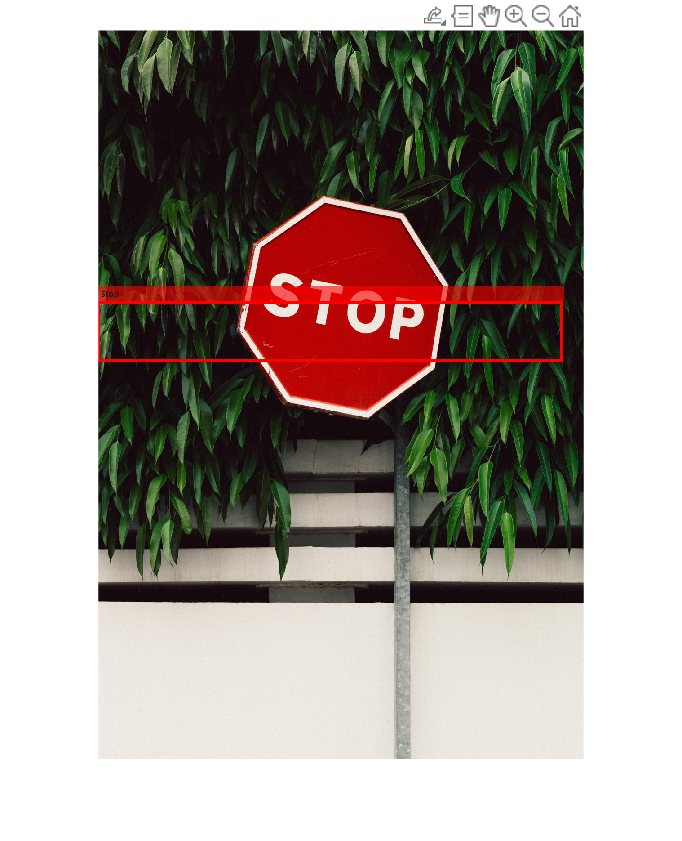


% Detect objects in the selected image
[bboxes, scores, labels] = detect(trainedDetector_4signs, I, 'Threshold', 0.01);

% Insert object annotations and display the result
detectedImg = insertObjectAnnotation(I, 'Rectangle', bboxes, labels,'LineWidth',6,'FontSize',18,'Color','red');
figure
imshow(detectedImg)